%upload image + downsize (optional)
emb_im2 = imread("013619~A-M-pyramid.tiff");
emb_im2_ds = imresize(emb_im2,0.4,'nearest');


%enhance contrast
emb2_adj = imadjust(emb_im2_ds);

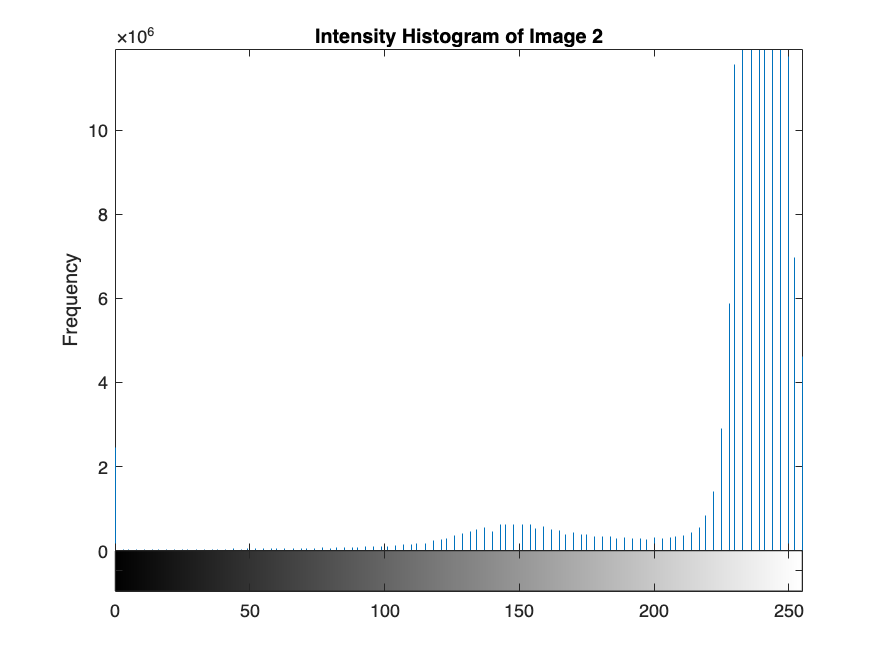

%generate intensity histogram
imhist(emb2_adj)
title('Intensity Histogram of Image 2')
ylabel('Frequency')
xlabel('Pixel Value')

%convert to BW
BW2 = emb2_adj > 200; %manual threshold value
%fill "holes" in objects
BW2_inverted = imcomplement(BW2);
BW2_filled = imfill(BW2_inverted, "holes");
%remove impurities
BW2_clear = bwareaopen(BW2_filled, 6000,4); %method needs to change


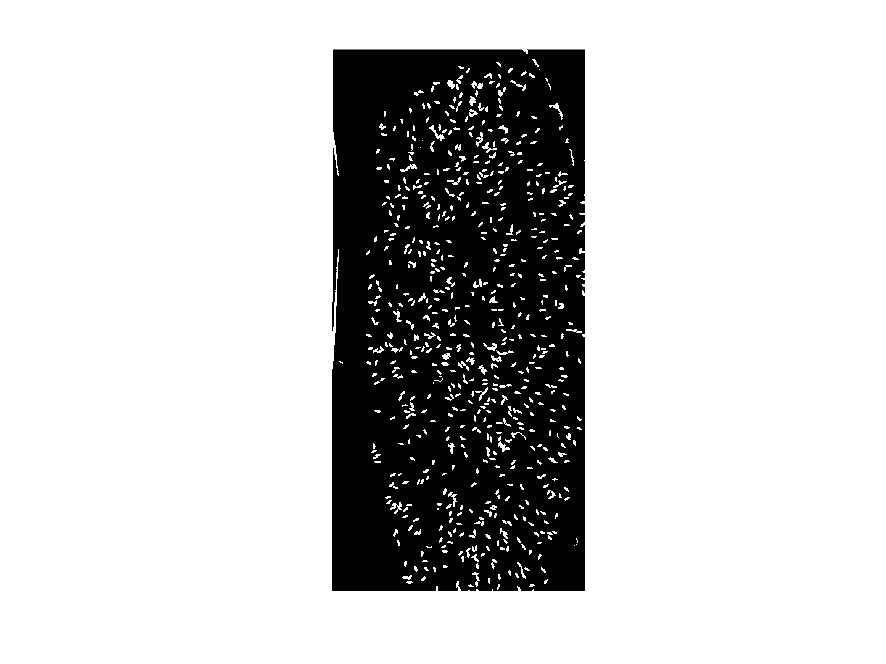

%imshow(BW2_clear)

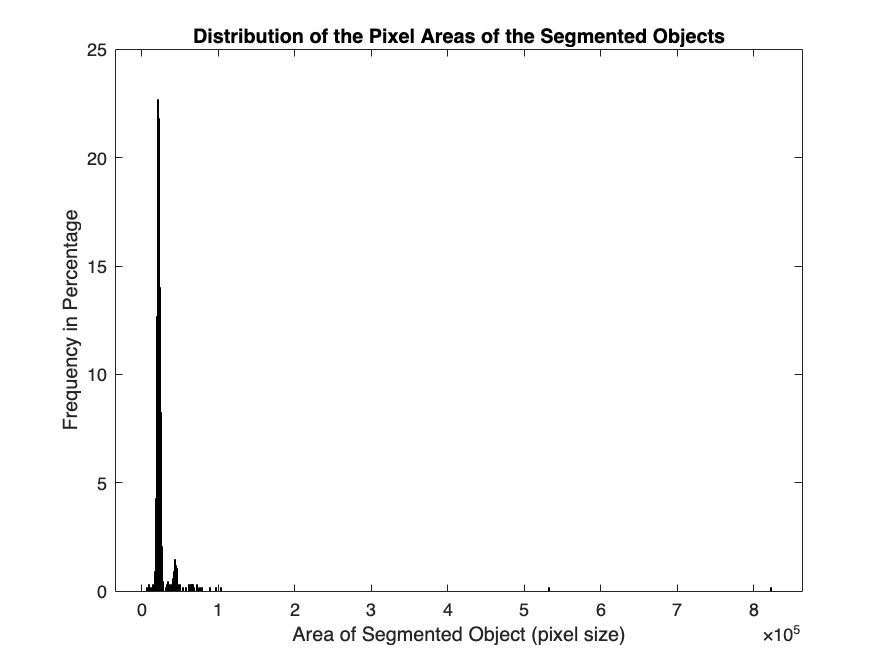

%visualize areas of each object cut out from bounding box
CC = bwconncomp(BW2_clear);
stats = regionprops("table",CC,"Area","BoundingBox");
area = stats.Area;
histogram(area,size(area,1),'Normalization', 'percentage');
xlabel('Area of Segmented Object (pixel size)');
ylabel('Frequency in Percentage');
title('Distribution of the Pixel Areas of the Segmented Objects');

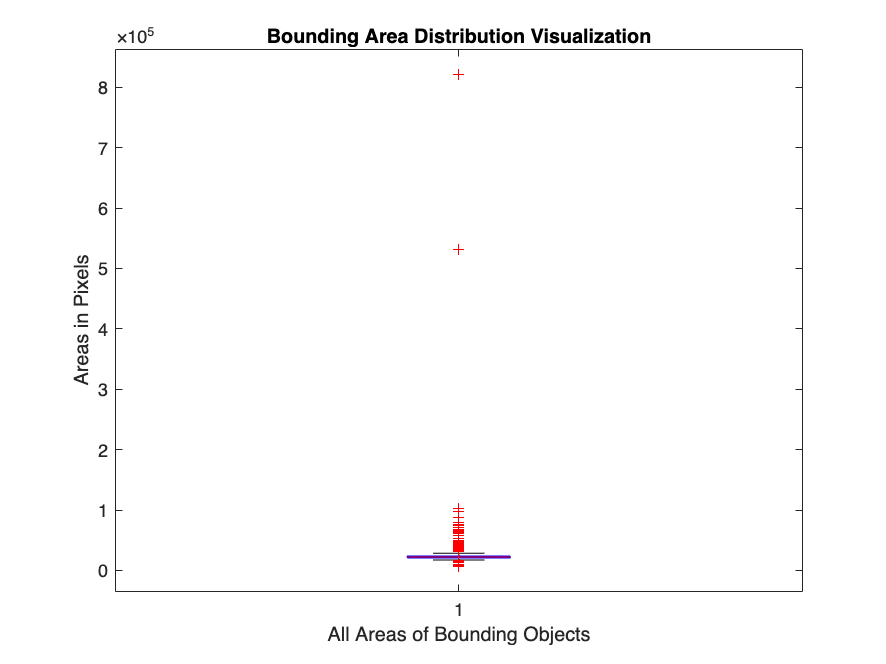

%create boxplot
figure;
boxplot(area);
xlabel('All Areas of Bounding Objects');
ylabel('Areas in Pixels');
title('Bounding Area Distribution Visualization');


%average area of each embryo
area_range = quantile(area,[0.125 0.875])

area_range =        19943       25682


%generate bw w/ connected embryos fully eliminated
emb2_selection = (area > area_range(1)) & (area < area_range(2));
BW2_clean = cc2bw(CC,ObjectsToKeep=emb2_selection);

%imshow(BW2_clean);

%label objects
label = bwlabel(BW2_clean,4);
max_labels = max(label, [],"all")

max_labels = 508

%create a black image (segmented area == true)
%outputImage = zeros(size(emb_im2_ds), 'like', emb_im2_ds);


% create a folder to save the images
output_folder = 'segmented_embryos2/';
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end


% Number of images to save 
num_images = 10; %change to actual label size

for l = 1:num_images 

    % stats of the labeled embryo 
    stats2 = regionprops(label==l, 'BoundingBox', 'Area');
    % extract bounding box of the labeled embryo
    boundingBox = stats2(1).BoundingBox; %index = 1 because only 1 region
    % crop the original image using the bounding box
    Cropped_image = imcrop(emb_im2_ds, boundingBox);
   % generate the filename with a specific pattern
    filename = sprintf('2embryo_%d.jpg', l);
    full_path = fullfile(output_folder, filename);
   
    
    % Save the image
    imwrite(Cropped_image, full_path);
   
end